# Discritisation

Disctitising the state equations for both temperature, SoC, and RC. S.t

xdot = f(x,i)

v_out = f(x(2)) + iR0 + x(3)

delta_temp =  

clear
file_loc = "..\..\..\cycle_exports\MOLI_28\";
cycle_number = "46";
filepath = strcat(file_loc, sprintf("MOLI_cycle_%s.mat", cycle_number));
load(filepath);
try
    solution_unbound
catch exception
    disp("Mhmmmmm")
end

solution_unbound = struct with fields:
            multipliers: [1×1 struct]
       computation_time: 24.8434
                      z: [792×1 double]
                   coll: [1×1 struct]
                      X: [130×2 double]
                      U: [130×1 double]
                      T: [130×1 double]
                      p: [13×1 double]
                     x0: [2×1 double]
                     t0: 0
                     tf: 1.5007e+04
                   Tdec: [130×1 double]
             z_orgscale: [792×1 double]
                   cost: [1×1 struct]
                    org: [1×1 struct]
                     dX: [258×2 double]
                     dU: [258×1 double]
                     Xp: {2×1 cell}
                    dXp: {2×1 cell}
                     Up: {[1×1 struct]}
                    dUp: {[1×1 struct]}
                  Error: [258×2 double]
                T_error: [259×1 double]
          ErrorRelative: [258×2 double]
        ConstraintError: [1300×6 double]
   

i_input = u1';
t_input = tt';
i_size = length(i_input);
v1 = ones(1,i_size)*0.1;
z = ones(1,i_size);
DT = zeros(1,i_size);
states = [v1; z; DT];
params = length(solution_unbound.p)

params = 15

for i = 1:i_size-1
i_curr = i_input(i);
Ts = t_input(i+1) - t_input(i);
[A, B] = discrit(solution_unbound.p,Ts);
states(:,i+1) = A*states(:,i) + B*[i_curr;i_curr.^2;states(1,i).*i_curr];
end
Sim_DT = states(3,:)

Sim_DT =          0    0.0005    0.0009    0.0015    0.0025    0.0036    0.0051    0.0071    0.0094    0.0120    0.0150    0.0174    0.0204    0.0252    0.0300    0.0333    0.0384    0.0483    0.0603    0.0713    0.0806    0.0987    0.1205    0.1379    0.1630    0.1857    0.2081    0.2349    0.2499    0.2769    0.2859    0.3130    0.3353    0.3591    0.3832    0.4055    0.4306    0.4511    0.4656    0.4847    0.5075    0.5248    0.5414    0.5565    0.5703    0.5861    0.6011    0.6153    0.6273    0.6376


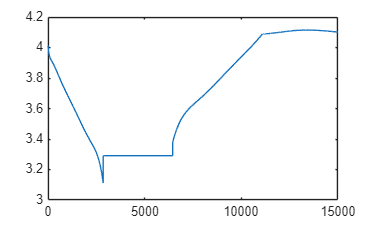

fix.poly.xe = zeros(params - 6,1);
Sim_V = polymodel(fix,solution_unbound.p,states(2,:),1)  + states(1,:) + i_input.*(solution_unbound.p(params-3));
plot(t_input,Sim_V)

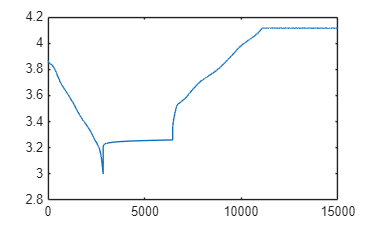

plot(tt,y)

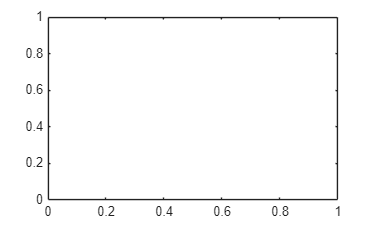

plot(tt,tp)

[trr,trw] = discrit_solver(t_input,i_input,solution_unbound.p,1)

trr =          0    0.0011    0.0021    0.0034    0.0055    0.0080    0.0110    0.0154    0.0198    0.0250    0.0307    0.0351    0.0406    0.0490    0.0570    0.0624    0.0706    0.0857    0.1033    0.1186    0.1310    0.1546    0.1815    0.2024    0.2315    0.2570    0.2816    0.3105    0.3265    0.3549    0.3642    0.3922    0.4148    0.4390    0.4632    0.4855    0.5104    0.5307    0.5450    0.5638    0.5862    0.6032    0.6194    0.6341    0.6476    0.6629    0.6776    0.6913    0.7030    0.7130


trw =     3.9144    3.9146    3.9146    3.9147    3.9148    3.9149    3.9150    3.9152    3.9154    3.9156    3.9158    3.9160    3.9162    3.9165    3.9168    3.9169    3.9172    3.9177    3.9181    3.9185    3.9187    3.9191    3.9194    3.9195    3.9195    3.9194    3.9191    3.9187    3.9184    3.9177    3.9174    3.9166    3.9157    3.9148    3.9137    3.9125    3.9112    3.9100    3.9091    3.9079    3.9063    3.9051    3.9038    3.9027    3.9016    3.9003    3.8990    3.8978    3.8967    3.8958
